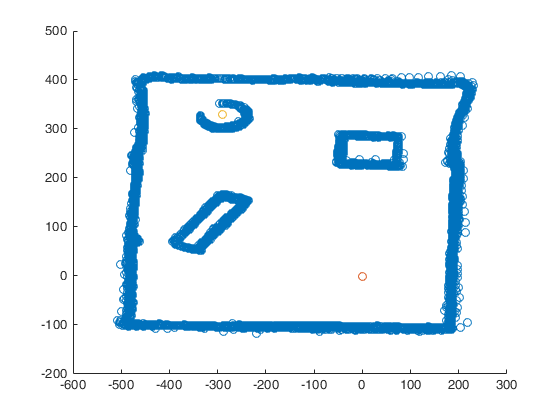

csv = csvread('points.csv');
X = csv(:,1);
Y = csv(:,2);
X = X - 2150;
Y = Y - 975;

sinkX = -290;
sinkY = 330;

hold off;
scatter(X,Y);
hold on;
scatter(0, 0);
scatter(sinkX, sinkY);
hold off;

bound = 1000;
sigma = 100;
scale = 5000;
sourceFcn = @(d) scale./(sqrt(2.*pi.*sigma.^2)) .* exp(-(d.^2)./(2.*sigma.^2))

sourceFcn = function_handle with value:
    @(d)scale./(sqrt(2.*pi.*sigma.^2)).*exp(-(d.^2)./(2.*sigma.^2))


sinkFcn = @(d) -sourceFcn(d)

sinkFcn = function_handle with value:
    @(d)-sourceFcn(d)


maxZ = sourceFcn(0);
fieldFcn = @(x,y) sourceFcn(sqrt(x.^2+y.^2))/maxZ + sinkFcn(sqrt((x-sinkX).^2+(y-sinkY).^2))/maxZ;

f = waitbar(1,"ree")

f =   Figure (TMWWaitbar) with properties:

      Number: []
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [585 376.8750 270 56.2500]
       Units: 'points'

  Show all properties


ptscale = 0.05;
for i=1:50:length(X)
    %i = 3001;
    disp(i)
    fieldFcn = @(x,y) fieldFcn(x,y) + min([1./(ptscale*sqrt((x-X(i)).^2+(y-Y(i)).^2).^2) 1]);
    waitbar(i/length(X));
end

     1



        1001

        2001

        3001

        4001

        5001



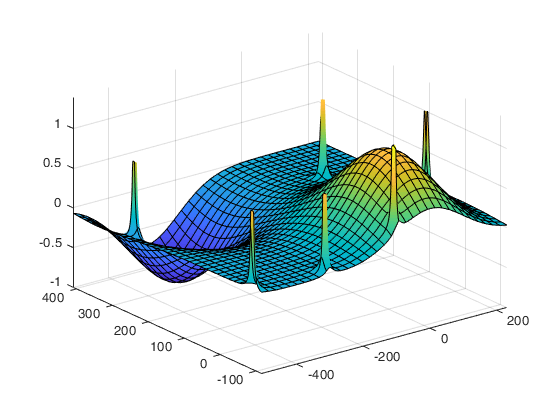

delete(f);
fsurf(fieldFcn, [min(X) max(X) min(Y) max(Y)]);


%fsurf(@(X,Y) sourceFcn(norm([X Y])))

hold off;

scatter(X,Y);

hold on;
scatter(0, 0);
scatter(sinkX, sinkY);
fcontour(fieldFcn, [min(X) max(X) min(Y) max(Y)],'LevelList', -maxZ:maxZ*2/500:maxZ)

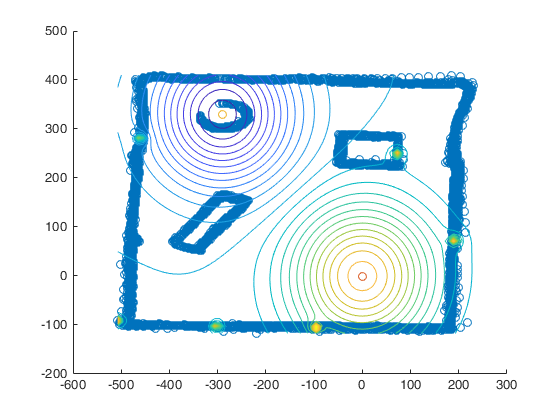


hold off;